## Simulation variables

SNRdB = 30;                % SNR in dB (Usused ATM)

totalNoSlots = 100;          % Number slots containing information simulated

perfectEstimation = false; % Perfect synchronization and channel estimation (Unused ATM)
rng("default");            % Set default random number generator for repeatability

fileID = fopen('Bits.bin','r'); %send bit file
fileID2 = fopen('RecBits.bin','w'); %recieve bit file

## Set 5G  variables

genvar5g

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: true
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: true
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


ans =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel config

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-C";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;

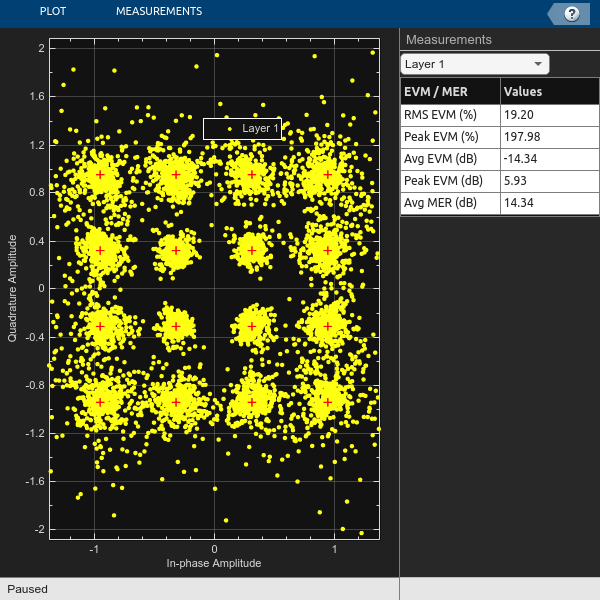

Slot 0. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   0
   1
   0
   1
   0
   1
   0
   1
   0


Slot 1. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Slot 2. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 3. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 4. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 5. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 6. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 7. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 8. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 9. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 10. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 11. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 12. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 13. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 14. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 15. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 16. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 17. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 18. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 19. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 20. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 21. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 22. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 23. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 24. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 25. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 26. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 27. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 28. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 29. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 30. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 31. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 32. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 33. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 34. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 35. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 36. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 37. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 38. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 39. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 40. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 41. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 42. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 43. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 44. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 45. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 46. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 47. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 48. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 49. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 50. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 51. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 52. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 53. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 54. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 55. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 56. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 57. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 58. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 59. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 60. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 61. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 62. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 63. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 64. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 65. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 66. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 67. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 68. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 69. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 70. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 71. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 72. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 73. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 74. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 75. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 76. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 77. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 78. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 79. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 80. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 81. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 82. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 83. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 84. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 85. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 86. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 87. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 88. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 89. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 90. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 91. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 92. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 93. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 94. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 95. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 96. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 97. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Slot 98. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


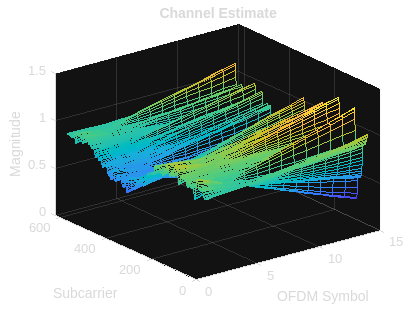

Slot 99. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1



constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements

% Initial timing offset
offset = 0;

longwave = 0.00001+0.00001i;


estChannelGrid = getInitialChannelEstimate(channel,carrier);
newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TransmitterEntity(carrier, pdsch, encodeDLSCH, harqEntity, nSlot, newPrecodingWeight, codeRate, fileID, nTxAnts, decodeDLSCH);


    chInfo = info(channel);
    maxChDelay = chInfo.MaximumChannelDelay;
    txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
    


    [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
    noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(rxWaveform));





    rxWaveform = rxWaveform + noise;
    longwave = cat(1, longwave,rxWaveform);
end



srec = 1;
erec = 15371;

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

     recWave = longwave(srec:erec,1);

     srec = srec + 15371;
     erec = erec + 15371;
   
    [decbits, statusReport, pdschEq] = RecieverEntity(carrier, pdsch, decodeDLSCH, harqEntity, recWave, offset, fileID2, newPrecodingWeight, trBlkSizes);
    disp("Slot "+(nSlot)+". "+statusReport);
    decbits

    constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
    constPlot.ShowLegend = true;
    % Constellation for the first layer has a higher SNR than that for the
    % last layer. Flip the layers so that the constellations do not mask
    % each other.
    constPlot(fliplr(pdschEq));

end 

## Plots

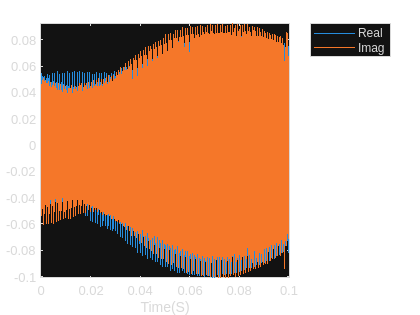

time = totalNoSlots*1e-3;
length = size(longwave);

x = 0:65e-9:time;
x = rot90(x);

x=x(1:length, 1);

%figure;
%plot(real(rxWaveform));
%hold on
%plot(real(txWaveform));
%xlabel('Time(S)')
%xlim([0.000000 100])



plot(x, real(longwave),x, imag(longwave));
legend("Real", "Imag")
xlabel('Time(S)')

## Local Functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB), which is the
% receiver SNR per RE and antenna, assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power by the IFFT size used in OFDM modulation, as
    % the OFDM modulator applies this normalization to the transmitted
    % waveform. Also normalize by the number of receive antennas, as the
    % channel model applies this normalization to the received waveform by
    % default. The SNR is defined per RE for each receive antenna (TS
    % 38.101-4).
    SNR = 10^(SNRdB/10); % Calculate linear noise gain
    N0 = 1/sqrt(2.0*nRxAnts*double(Nfft)*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end
    
function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end

function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate.

    % Linearize 4-D matrix and reshape after multiplication
    K = size(estChannelGrid,1);
    L = size(estChannelGrid,2);
    R = size(estChannelGrid,3);
    estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
    estChannelGrid = estChannelGrid*W;
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end